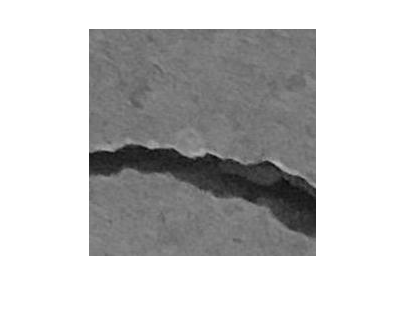

img = rgb2gray(imread("00187.jpg"));
imshow(img)

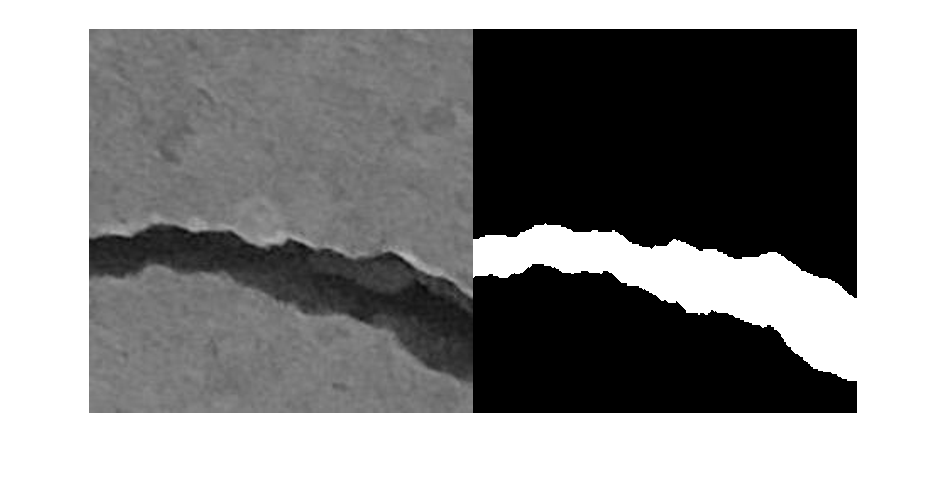


BW = imbinarize(img);
BW = ~BW;

montage({img, BW})

nnz(BW)

ans = 7846

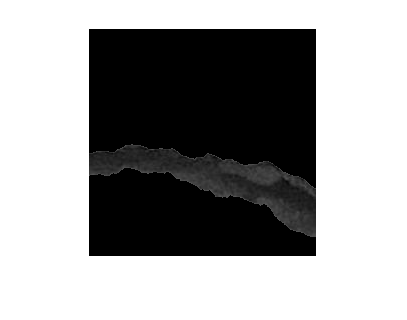


maskedImg = img;
maskedImg(~BW) = 0;
imshow(maskedImg)

graythresh(img)

ans = 0.3255

graythresh(img) *255

ans = 83

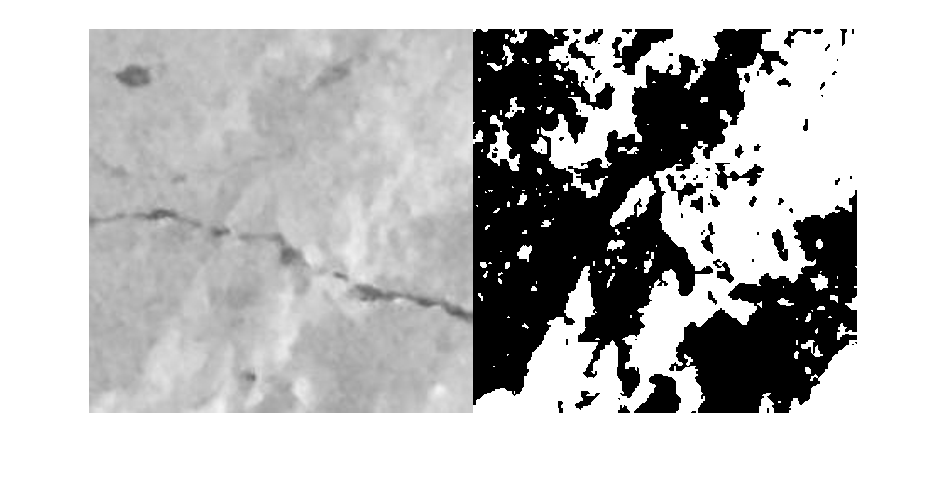

img = rgb2gray(imread("00051.jpg"));
BW = imbinarize(img);
montage({img,BW})

graythresh(img)

ans = 0.7451

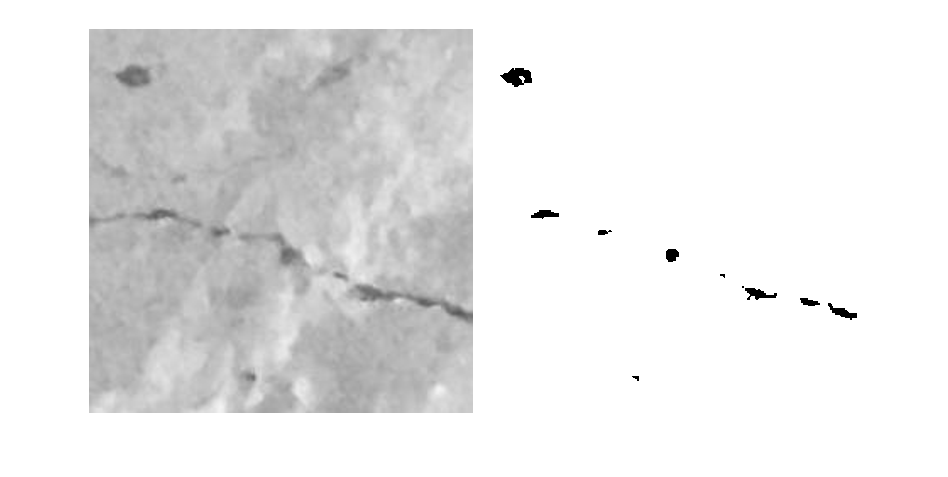

img = rgb2gray(imread("00051.jpg"));
BW = imbinarize(img,0.503);
montage({img,BW})

graythresh(img)

ans = 0.7451

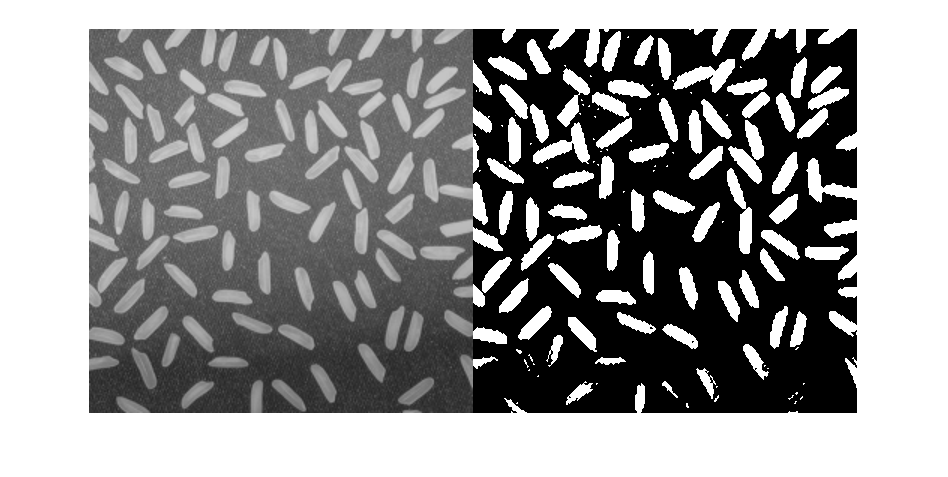

img = imread("rice.png");
BW = imbinarize(img);
montage({img,BW})

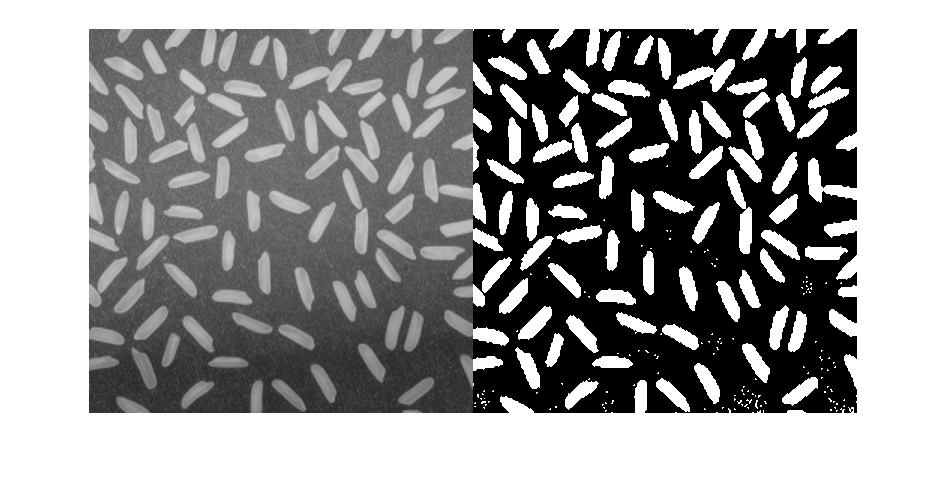

img = imread("rice.png");
BW = imbinarize(img, "adaptive");
montage({img,BW})

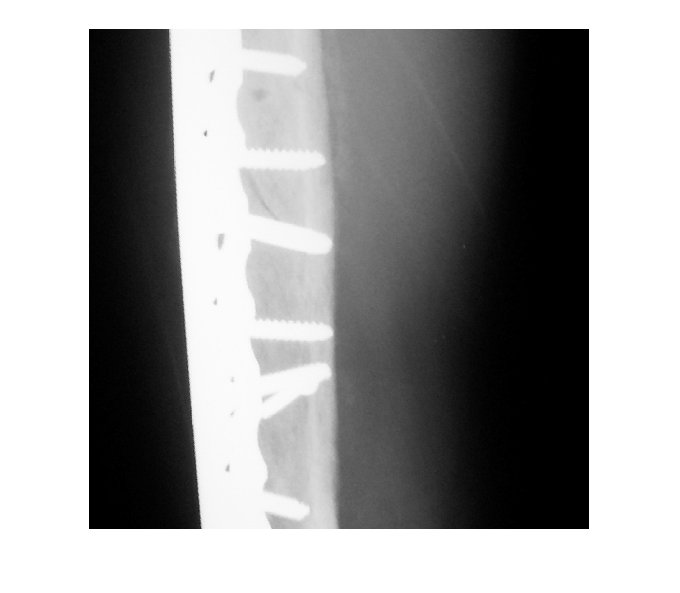

img = imread("armxray.png");
imshow(img)

threshvalues = multithresh(img,3)

threshvalues = 1×3 uint8 row vector
    54   147   223


labels = imquantize(img,threshvalues)

labels =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1    

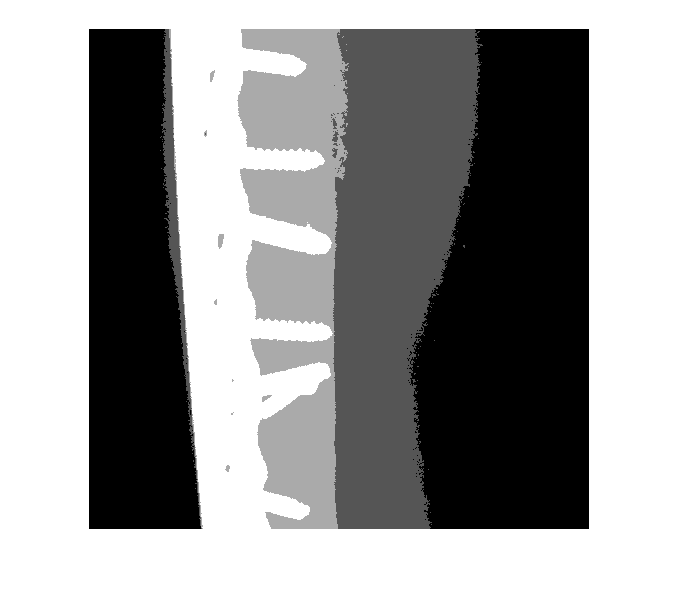

imshow(labels,[])

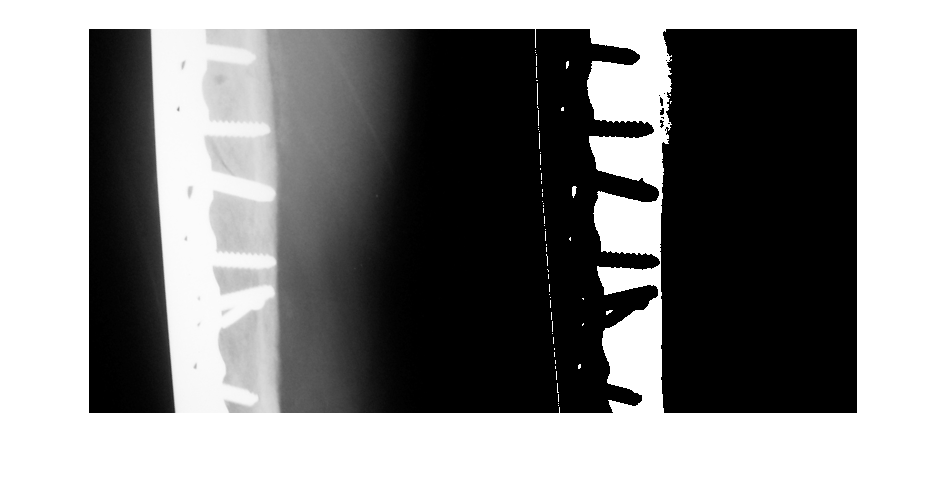

label3 = labels == 3;
montage({img,label3})